Reto 1: Parte 2

Profundización II: Electromedicina

Restauración de imágenes de leucocitos de un canino.

Leandro Ramos - 219160260es

Brandon Rosero - 219160289

Inicio del código.

Limpiar espacion de trabajo y agregar carpeta de funciones.

clc; clear variables; close all
addpath 'C:\Users\elean\Documents\MATLAB\funciones'

Leer imagen banco de imagenes. 1 Lista de pulmones con pneumonia, 2 lista de sanos.

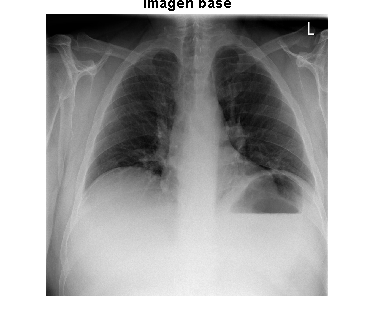

a = leerRx(26,1); %almacena todas las imagnes de la lista 1 o 2
for i = 2: 2
I = a{i};
end
figure
imshow(I);
title("Imagen base");

I = rgb2gray(I);

Identificar posible ruido en imagen. 

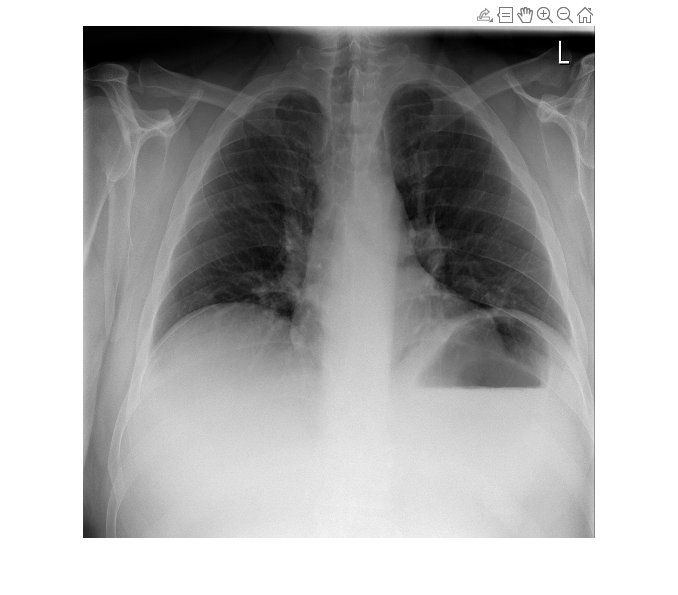

Ir = imcrop(I); %seleccionar region uniforme

Usar una pdf para identificar ruido. 

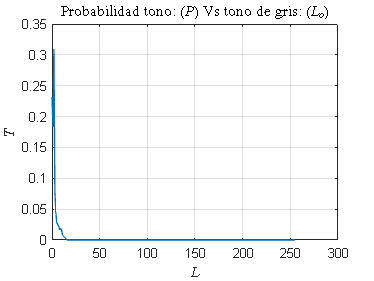

[M , N] = size(Ir);
p = imhist(Ir)/(M*N);
L = 0:255;
figure
plot(L,p);
grid("on");
title("Probabilidad tono: $(P)$ Vs tono de gris: $(L_o)$",LineWidth = 3,Interpreter="latex");
ylabel("$T$",LineWidth = 3,Interpreter="latex");
xlabel("$L$",LineWidth = 3,Interpreter="latex");

Con la informacion almacenada en las varialbes P y L se realiza una estimacion gausiana usando la app de matlaba "Curve Fitter"

[xData, yData] = prepareCurveData( L, p );

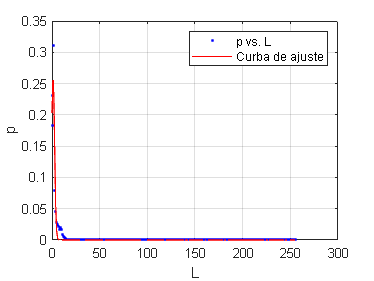


% Set up fittype and options.
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [0.688423645320197 7 0.399916626116222];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'p vs. L', 'Curba de ajuste', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'L', 'Interpreter', 'none' );
ylabel( 'p', 'Interpreter', 'none' );
grid on

disp(fitresult);

     General model Gauss1:
     fitresult(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =       0.257  (0.244, 0.2699)
       b1 =       1.126  (0.9983, 1.254)
       c1 =       2.286  (2.087, 2.485)


Realizar un analisis en Fourier para identificar el nivel de ruido mas detallado. 

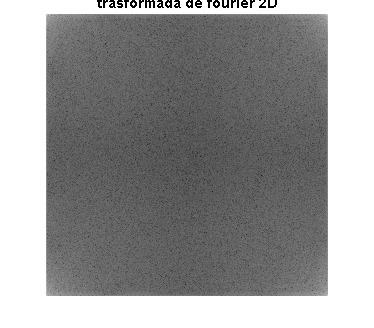

I = double(I);
If = fft2(I); %trasformada de fourier 2d de imagen.
Ifa = abs(If);
figure
imshow((log(1+(Ifa))),[]);
title("trasformada de fourier 2D");

[~,~,H] = masnotch(I,50,25); % forma del filtro

limite = 0.9974

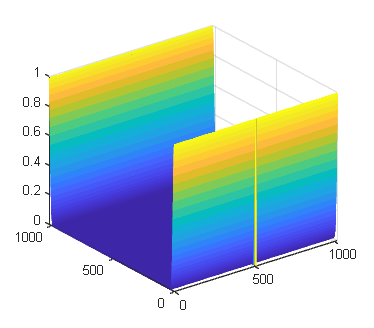

H = fftshift(H);
mesh(H);

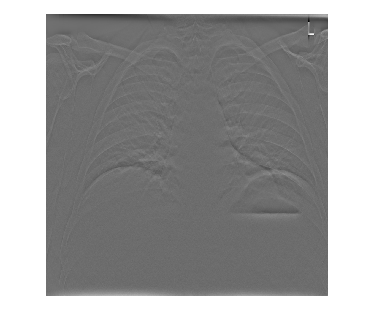


In = If.*H;
In = real(ifft2(In));
In = notch_optimo(I,In,1); 
imshow(In ,[]);

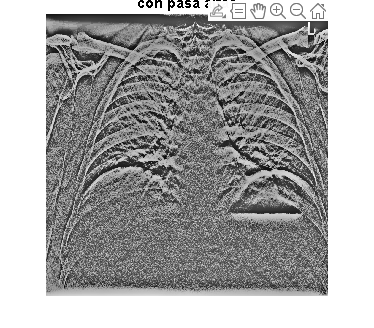

In2 = ecualizarmach(In);
In2 = ihig(In2,8);
figure
imshow(In2,[]);
title("con pasa altas");

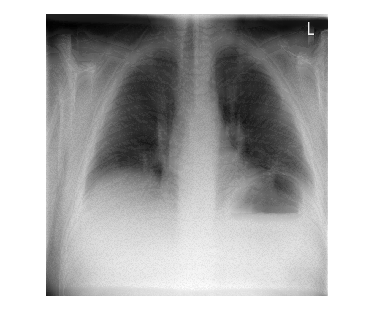

In2 = notch_optimo(I,In2,1);
figure
imshow(In2,[]);

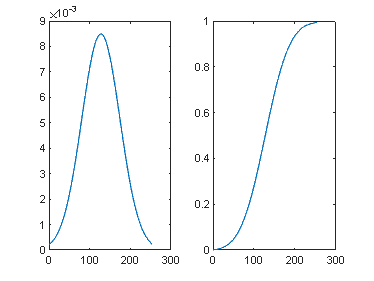

%Td = 1.009.^L; % forma del histograma acomulado deceado
gaus = normpdf(L,127.5,47);
Td = cumsum(gaus);
figure
subplot(1,2,1)
plot(L,gaus)
subplot(1,2,2)
plot(L,Td);

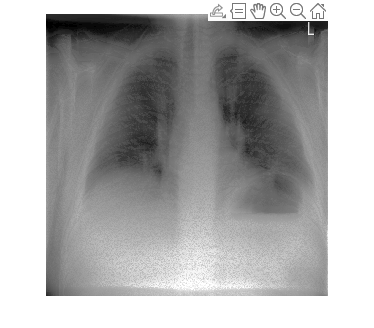

In3 = ecualizarf(In2,Td);
figure
imshow(In3,[]);

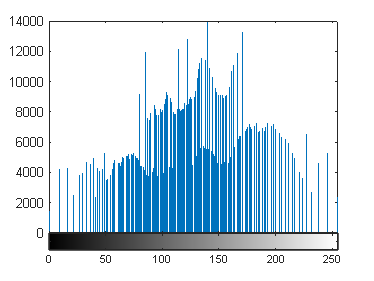

figure
imhist(In3);

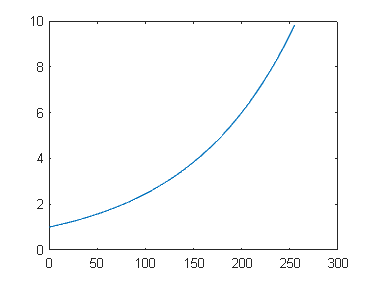

Td = 1.009.^L; % forma del histograma acomulado deceado
figure
plot(L,Td);

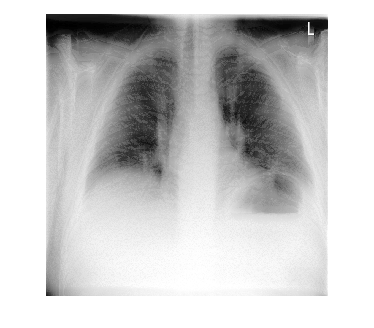

In3 = ecualizarf(In2,Td);
figure
imshow(In3,[]);

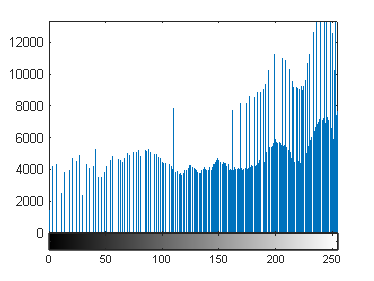

figure
imhist(In3);